This function controls two RC servomotors on Robot Tug, the inputs are rudderAngle:the rudder in open loop position mode -45 to 45 degress and propSpeed: the propellor speed in open loop speed control from full rerverse to full forward,as well as the rudderServo and propServo Pi objects

Hook Pi pin IO4 to rudder Motor, IO5 to propellor Motor, IO22 to turntable motor, Ground Pi to Servo Ground. 

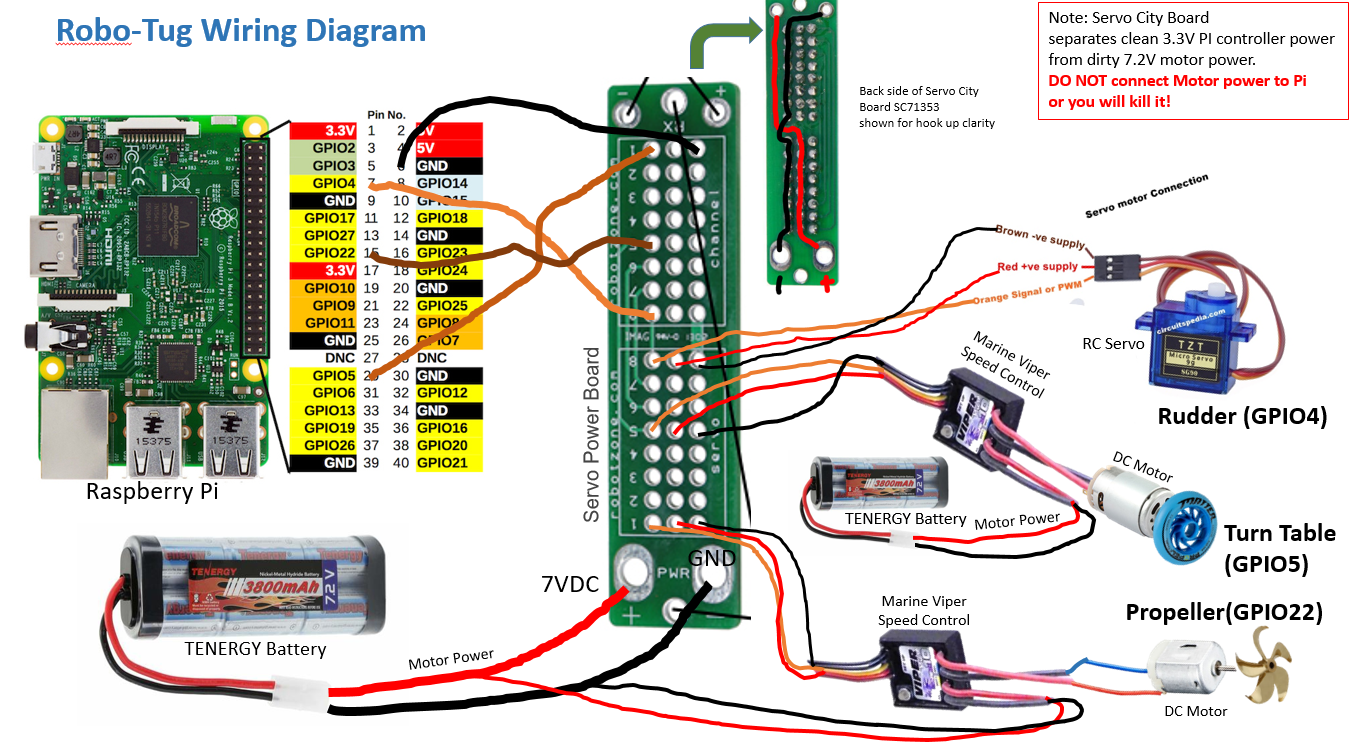

Scale rudder Input  command -45 to 45 to be 0-180 for rudder  (90 is centered). Scale turntable to turn when rudder is not zero

Scale propellor input command full reverse (-2ft/sec) to full forward (2ft/sec) to be 0-180 for propellor (90 is stop)

Need to run TugRaspPiSetup function first to create a Raspberry-Pi and servo objects before using this function

D. Barrett March 2022 (Revision B).

function commandComplete = TugServoControl_RevB(rudderServo, propServo, ttServo, rudderAngle, propSpeed)

    scaledRudderAngle = (rudderAngle+45)*2.0; % input rudderAngle: -45 to 45. Output: 0 to 180.
    % Rudder angle is reversed from how the servo/turntable interact with tug
    scaledRudderAngle = 180-scaledRudderAngle; % reverse the input accordingly
    % Limit rudder command from 0 to 140 to prevent servo buzzing, from experimentation
    scaledRudderAngle=min(max(scaledRudderAngle,0),150);
    writePosition(rudderServo, scaledRudderAngle); % Set 'safe' rudder angle

    % Turntable speed emulates the turning of the boat,
    % so it is set to the rudder angle.
    writePosition(ttServo, scaledRudderAngle); % Set turntable rotation.

    dampen = 1; % Optional factor by which to reduce propellor speed (to reduce noise). 1 is normal.
    scaledPropSpeed = (propSpeed*45/max(dampen,1))+90; % input propSpeed: 0 to 1
    writePosition(propServo, scaledPropSpeed); % Set propellor speed

    commandComplete = 1;

end